# Assignment 2: Task 2

## Load experiment data

if (~exist("session2","var"))
    load("group-01.02.mat");
end

f = session2.task2.frequency;
R0 = session2.task2.antennas_distance;
H = session2.task2.reflection_height(1);
epsilon1 = 8.854e-12;
epsilon2 = session2.task2.dielectric_prermittivity; epsilon2 = epsilon2 * 8.8541878128e-12;
phi = 0.2*pi; % In the setup this is pi/2
tau = 0*pi; % In the setup this is 0

## Free space

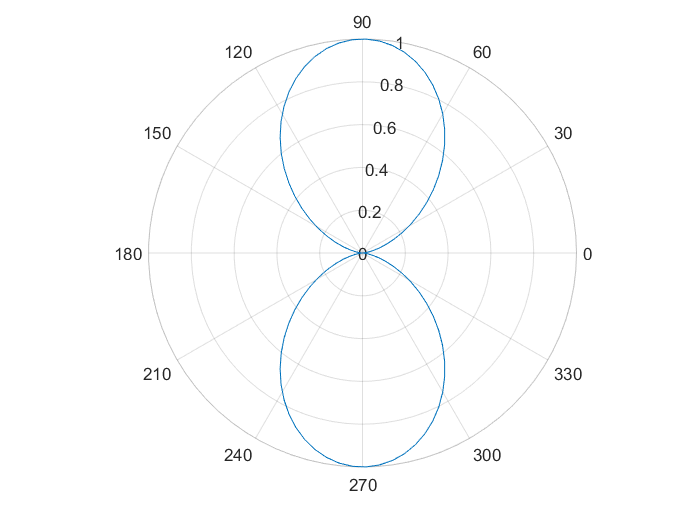

% Vertical
tau = 0;
phi = 0.5*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon1)

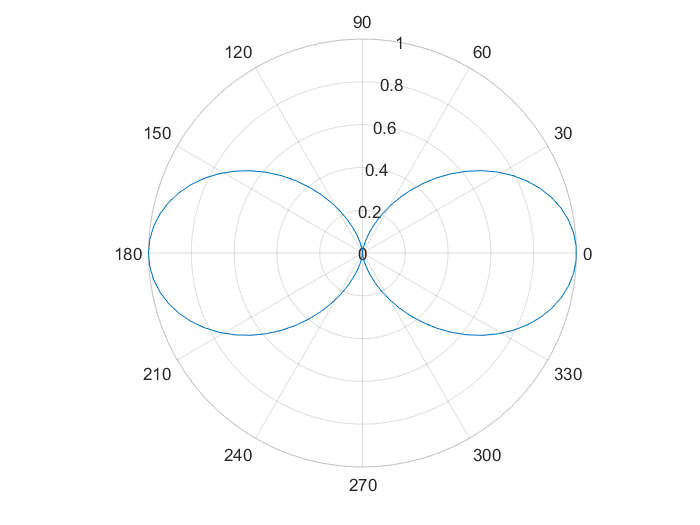

% Horizontal
tau = 0;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon1)

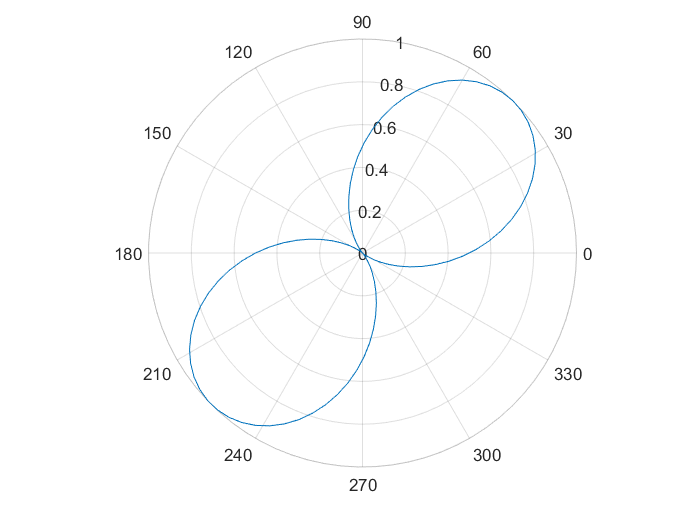

% Circular
tau = 0.25*pi;
phi = 0.0*pi;
angular_pattern(f,R0,H,phi,tau,epsilon1,epsilon1)

## Metallic plate